# ***Wireless Communications***

## ***CA1***

### ***Section 1***

### ***Part 1 - الف***

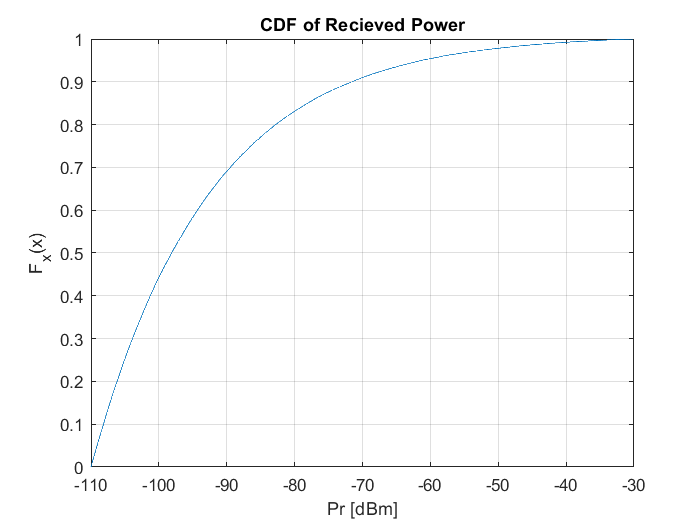

d0 = 10;
D = 1000;
n = 4;
N = 1e5;    % Number of users
P0 = 1e-6;
P0_dbm = 10*log10(P0) + 30;
d = d0 + (D-d0)*rand(N,1);
d_sorted = sort(d);
Pr_dbm = P0_dbm - 10*n*log10(d_sorted/d0);
figure(1);
cdfplot(Pr_dbm);
xlabel('Pr [dBm]');
ylabel('F_x(x)');
title("CDF of Recieved Power");
grid on;

### ***Part 2 - ب***

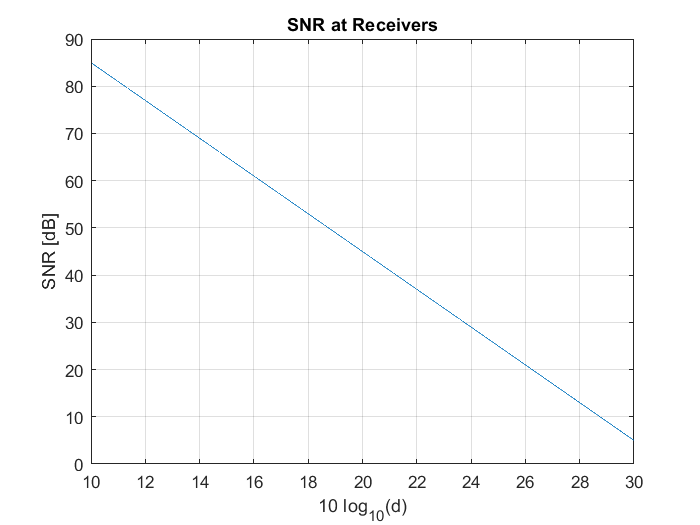

N0_dbm = -175;
N0_db = N0_dbm - 30;
N0 = 10^(N0_db/10);
BW = 1e6;
Pn = N0 * BW;
Pn_dbm = 10*log10(Pn) + 30;
SNR_db = Pr_dbm - Pn_dbm;
figure(2);
plot(10*log10(d_sorted),SNR_db);
xlabel("10 log_{10}(d)");
ylabel("SNR [dB]");
title("SNR at Receivers");
grid on;

### ***Part 3 - ج***

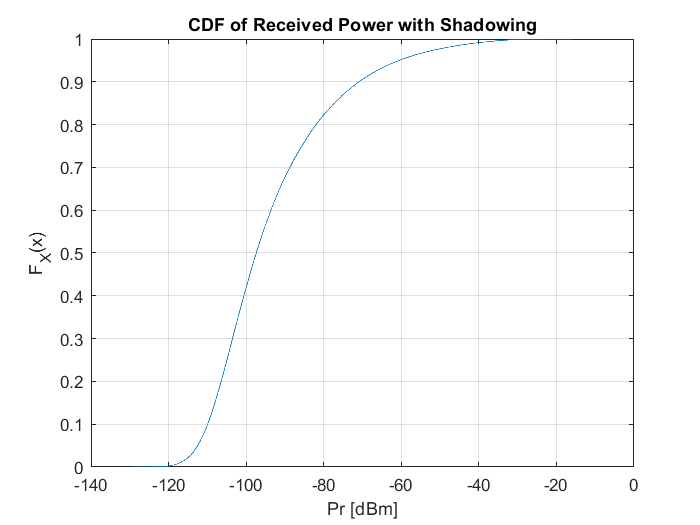

sigma = 5;
X_db = sigma*randn(N,1);
Pr_dbm_shadowing = P0_dbm - 10*n*log10(d_sorted/d0) + X_db;
figure(3);
cdfplot(Pr_dbm_shadowing);
xlabel("Pr [dBm]");
ylabel("F_X(x)");
title("CDF of Received Power with Shadowing");
grid on;

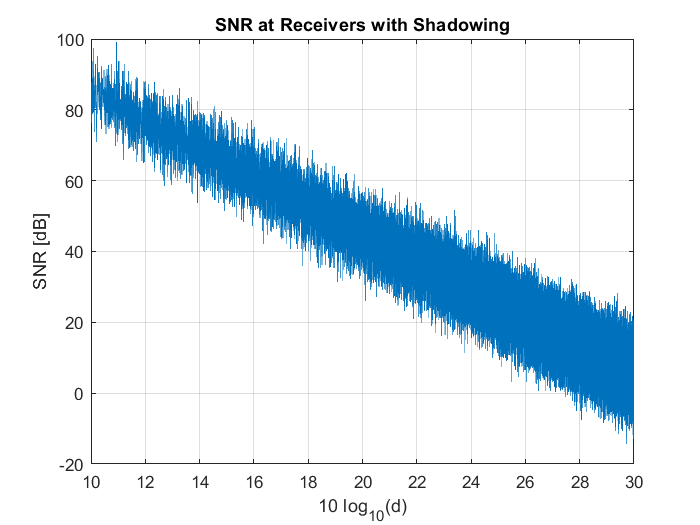

SNR_db_shadowing = Pr_dbm_shadowing - Pn_dbm;
figure(4);
plot(10*log10(d_sorted),SNR_db_shadowing);
xlabel("10 log_{10}(d)");
ylabel("SNR [dB]");
title("SNR at Receivers with Shadowing");
grid on;

### ***Part 4 - د***

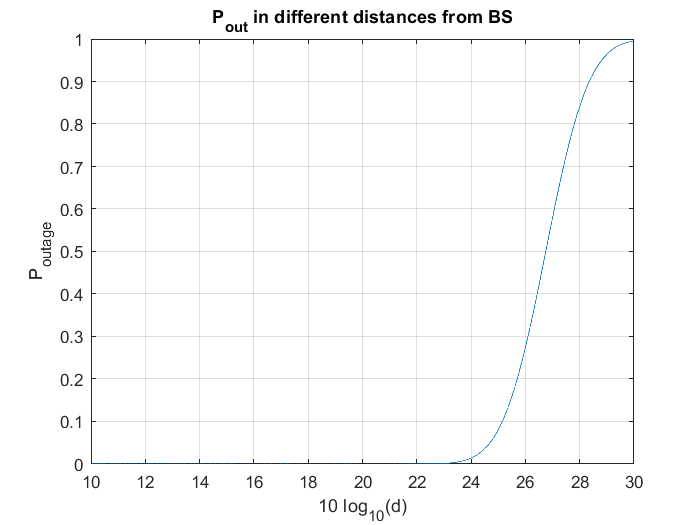

SNR_min = 18;
cdf_arg = SNR_min - (P0_dbm - 10*n*(log10(d_sorted/d0)) - Pn_dbm);
P_out = 1/2*(1+erf(cdf_arg/(sqrt(2)*sigma)));
figure(5);
plot(10*log10(d_sorted),P_out);
xlabel("10 log_{10}(d)");
ylabel("P_{outage}");
title("P_{out} in different distances from BS");
grid on;

### ***Part 5 - ه***

SNR_db = Pr_dbm - Pn_dbm;
idx = find(SNR_db <= SNR_min);
d2 = d_sorted(idx(1));
d1 = d0;
s_comp = pi*(d2^2 - d1^2);

Pr_D = P0_dbm - 30 - 10*n*log10(D/d0);
Pr_min = 10*log10(N0 * BW) + SNR_min;
a = (Pr_min - Pr_D)/sigma;
b = 10*n*log10(exp(1))/sigma;
C = qfunc(a) + exp((2-2*a*b)/(b^2))*qfunc((2-a*b)/b);
s_theory = pi * D^2 * C;

Coverage_Percent = s_comp/(pi*D^2);
disp("Coverage Percent:");

Coverage Percent:


disp(Coverage_Percent);

    0.2238



Coverage_Percent_theory = s_theory/(pi*D^2);
disp("Coverage Percent in Theory:");

Coverage Percent in Theory:


disp(Coverage_Percent_theory);

    0.2632



disp("Theoratical Coverage Area:")

Theoratical Coverage Area:


disp(s_theory)

   8.2688e+05



disp("Coverage Area:")

Coverage Area:


disp(s_comp);

   7.0300e+05

